# Project 3 (Weather Balloon)

12.35 in book

%{
t
   originally from 'MATLAB for Engineers', sixth edition, by Holly Moore,
   chapter 12, problem 12.35
Author: Tori Testa
Version: 1.0
Date: 2026-04-04
Purpose:
   - modeling the behavior of a weather balloon after its launch
Input:
   -
Output:
   -
Engineering Algorithems:
   -
MATLAB tools/functions:
   -
Reflection
   - 
%}

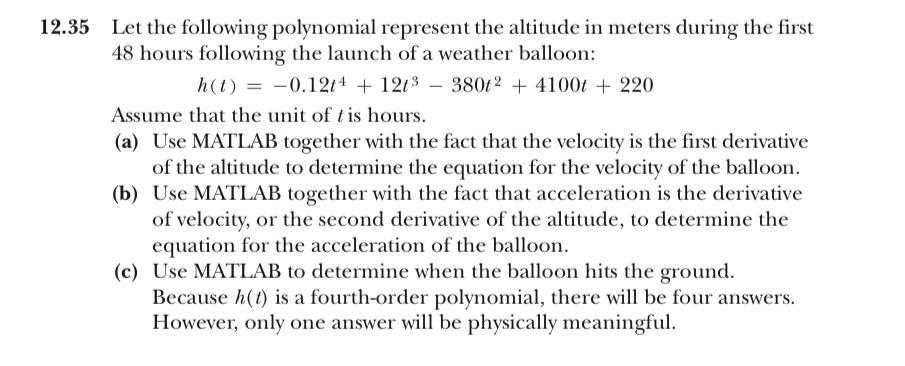    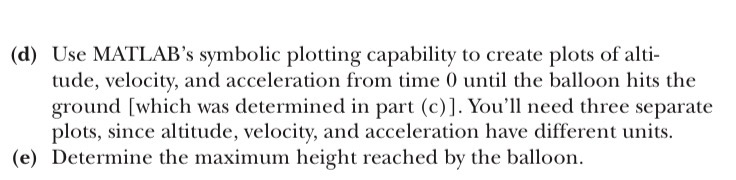

clc
clear
syms t  % creates t as a symbolic variable
% the altitude of the balloon for the 48 hours since its release
h = (-0.12)*(t^4) + (12)*(t^3) - (380)*(t^2) + (4100*t) + 220; % defines the altitude equation

% determine equation for velocity of balloon
v = diff(h, t);  % defines the velocity as derivative of h with respect to t
disp('Velocity:') 

Velocity:


disp(v);  % displays the equation for velocity

$$-\frac{12\,t^{3}}{25}+36\,t^{2}-760\,t+4100$$

% determine equation for acceleration of balloon
a = diff(v, t); % defines the acceleration as derivative of v with respect to t
disp('Acceleration:');

Acceleration:


disp(a);  % displays the equation for acceleration

$$-\frac{36\,t^{2}}{25}+72\,t-760$$

% determine when the balloon will hit the ground 

tGround = solve(h == 0, t); % solves for where the balloon is at height 0
tGround = double(tGround); % gives numeric answer, rather than symbollic
tGround = tGround(tGround >= 0); % only includes positive times
real_values = tGround(imag(tGround) == 0); % only includes real time values
fprintf('The balloon will hit the ground at t = %g seconds', real_values) % displays the time the balloon will hit the ground

The balloon will hit the ground at t = 51.1942 seconds


t_vals = linspace(0,48); % evenly spaced t values from 0 to 48 hours
 % makes sure the altitude and time have the same amount of values
v_vals = double(subs((diff(h,t)), t, t_vals)); % makes sure the velocity and time have the same amount of values
a_vals = double(subs(a, t, t_vals)); % makes sure the acceleration and time have the same amount of values

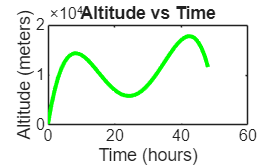

% plots altitude vs time
T = 0:48; % defines time on the interval 0 hours to 48 hours
hf = (-0.12)*(T.^4) + (12)*(T.^3) - (380)*(T.^2) + (4100*T) +220; % defines the height
plot(T, hf, 'g-', 'LineWidth',2) % makes the line green with width of 2
xlabel('Time (hours)')  %labels the x axis as time in hours
ylabel('Altitude (meters)')  %labels the y axis as altitude
title('Altitude vs Time')  % creates a title for the graph

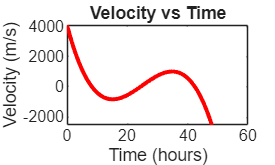

% plots velocity vs time
plot(t_vals, v_vals, 'r-', 'LineWidth',2) % makes the line red with width of 2
xlabel('Time (hours)') % labels the x axis as the time in hours
ylabel('Velocity (m/s)') % labels the y axis as velocity
title('Velocity vs Time') % creates a title for the graph

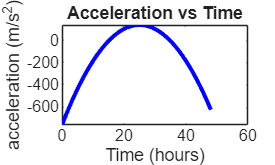

% plots acceleration vs time
plot(t_vals, a_vals, 'b-', 'LineWidth',2) % makes the line blue and width of 2
xlabel('Time (hours)')  % lables the x axis as time in hours
ylabel('acceleration (m/s^2)')  % labels the y axis as acceleration
title('Acceleration vs Time')  % creates a title for the graph

% determine the max height reached by the balloon (v of balloon is zero at
% max height)
maxt = solve(v == 0, t);  % determines max height by solving where velocity is 0
maxh = double(maxt); % outputs a numeric value
maxh = maxh(maxh >= 0); % ensures a positive value
realMaxh = maxh(imag(maxh) == 0); % outputs only real values
real1 = realMaxh(3); % outputs the absolute max, instead of the relative maxes
fprintf('The max height of the balloon is %g meters.', real1) % displays the max height

The max height of the balloon is 42.4248 meters.